clear all, clc, close all

s = tf('s')


s =
 
  s
 
Continuous-time transfer function.




k = 1

k = 1

T = 2

T = 2


% return

gr_linii = 3;
t = (0:0.1:30)';

disp('-------------------------------')

-------------------------------



disp('Inercyjny n-rzedu (4)')   % 4 rzad

Inercyjny n-rzedu (4)


in4 = k/((s*T+1)^4)


in4 =
 
                  1
  ----------------------------------
  16 s^4 + 32 s^3 + 24 s^2 + 8 s + 1
 
Continuous-time transfer function.



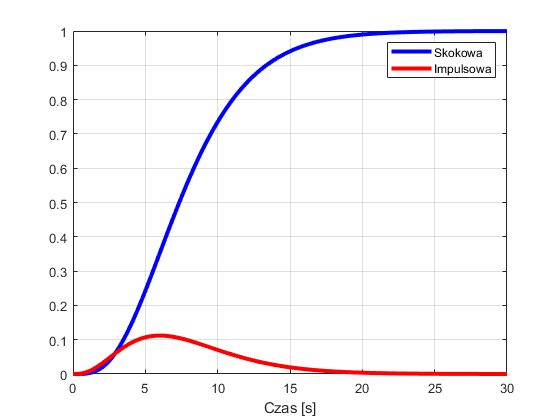


y1 = step(in4,t);
y2 = impulse(in4,t);
plot(t,y1, 'b',t,y2, 'r','LineWidth',gr_linii)
legend('Skokowa','Impulsowa')
xlabel('Czas [s]')

grid on

t = (0:0.1:50)';

T0 = 2.6

T0 = 2.6000

B = 12.2

B = 12.2000

T1 = B - T0

T1 = 9.6000

disp('Obiekt ktorym przyblizamy')

Obiekt ktorym przyblizamy


przybl = tf(k,[T1 1],'InputDelay',T0)


przybl =
 
                    1
  exp(-2.6*s) * ---------
                9.6 s + 1
 
Continuous-time transfer function.



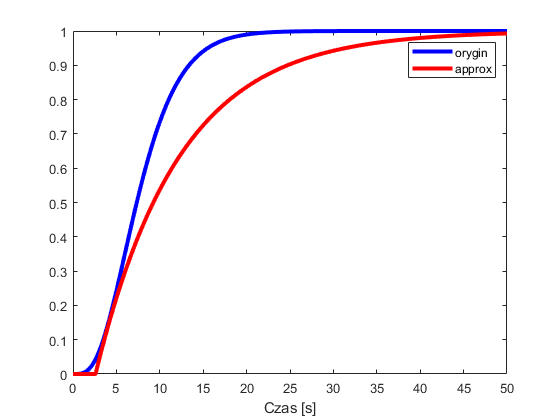


figure(2)
y3=step(in4,t);
%hold on
y4=step(przybl,t);
plot(t,y3, 'b','LineWidth',gr_linii)
hold on
plot(t,y4, 'r','LineWidth',gr_linii)

legend('orygin','approx')
xlabel('Czas [s]')